load('Controllers/PolePlacementWout/DT_SS_model_G1.mat')

Load ss matrices

A = G1.A

A =     0.9999    0.0007    1.0000         0         0         0
   -0.2529    3.5807         0    1.0000         0         0
         0         0         0         0         0         0
    0.6244   -4.7596         0         0    1.0000         0
   -0.4904    2.7727         0         0         0    1.0000
    0.1188   -0.5938         0         0         0         0


B = G1.B

B =     0.0002
    0.0426
   -0.0480
   -0.0916
    0.0492
         0


C = G1.C

C =      1     0     0     0     0     0
     0     1     0     0     0     0


D = G1.D

D =      0
     0


create state space object

sys = ss(A, B, C, D)


sys =
 
  A = 
              x1         x2         x3         x4         x5         x6
   x1     0.9999  0.0006759          1          0          0          0
   x2    -0.2529      3.581          0          1          0          0
   x3          0          0          0          0          0          0
   x4     0.6244      -4.76          0          0          1          0
   x5    -0.4904      2.773          0          0          0          1
   x6     0.1188    -0.5938          0          0          0          0
 
  B = 
              u1
   x1  0.0001967
   x2    0.04261
   x3   -0.04803
   x4   -0.09163
   x5    0.04923
   x6          0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



sys = d2c(sys)

Error using DynamicSystem/d2c (line 34)
The first input argument of the "d2c" command must be a discrete-time model.

check controlable

Co = ctrb(sys)

Co =     0.0002   -0.0478   -0.0478   -0.0477   -0.0476   -0.0476
    0.0426    0.0609    0.0767    0.0850    0.0887    0.0894
   -0.0480         0         0         0         0         0
   -0.0916   -0.1535   -0.2017   -0.2278   -0.2403   -0.2440
    0.0492    0.1181    0.1670    0.1942    0.2080    0.2132
         0   -0.0253   -0.0418   -0.0512   -0.0562   -0.0583


unco = length(A) - rank(Co)

unco = 0

check open loop eigenvalues

E = eig(A)

E =    0.5964 + 0.0000i
   0.9926 + 0.1066i
   0.9926 - 0.1066i
   1.0000 + 0.0000i
   0.9988 + 0.0000i
   0.0000 + 0.0000i


Desired closed loop eigenvalues

P = [-0.1 -0.2 -0.3 -0.4 -0.6 -0.8]

P =    -0.1000   -1.0000   -2.0000   -8.0000  -16.0000  -32.0000


solve for K

K = place(A, B, P)

K =    1.0e+13 *

   -0.0354   -7.6048   -0.0354   -7.6103   -7.6158   -7.6211


check for closed loop eigenvalues

A_cl = A - B*K

A_cl =    1.0e+12 *

    0.0001    0.0150    0.0001    0.0150    0.0150    0.0150
    0.0151    3.2405    0.0151    3.2429    3.2452    3.2475
   -0.0170   -3.6529   -0.0170   -3.6556   -3.6582   -3.6608
   -0.0325   -6.9680   -0.0324   -6.9731   -6.9781   -6.9830
    0.0174    3.7441    0.0174    3.7468    3.7495    3.7521
    0.0000   -0.0000         0         0         0         0


Create closed loop system

syscl = ss(A_cl, B, C, D)


syscl =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1   6.965e+07   1.496e+10   6.962e+07   1.497e+10   1.498e+10   1.499e+10
   x2   1.509e+10   3.241e+12   1.508e+10   3.243e+12   3.245e+12   3.247e+12
   x3  -1.701e+10  -3.653e+12    -1.7e+10  -3.656e+12  -3.658e+12  -3.661e+12
   x4  -3.245e+10  -6.968e+12  -3.244e+10  -6.973e+12  -6.978e+12  -6.983e+12
   x5   1.744e+10   3.744e+12   1.743e+10   3.747e+12   3.749e+12   3.752e+12
   x6      0.1188     -0.5938           0           0           0           0
 
  B = 
              u1
   x1  0.0001967
   x2    0.04261
   x3   -0.04803
   x4   -0.09163
   x5    0.04923
   x6          0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



syscl = c2d(syscl)
sys = c2d(sys)

chec step response

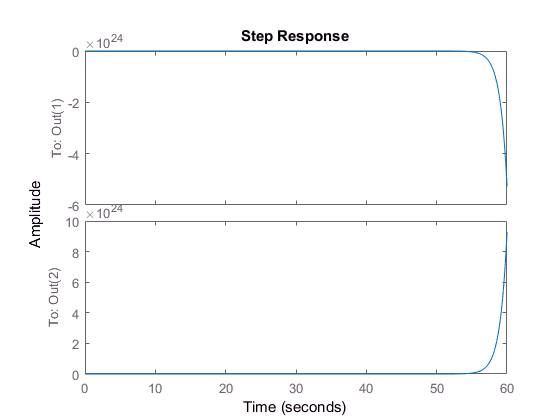

step(sys)

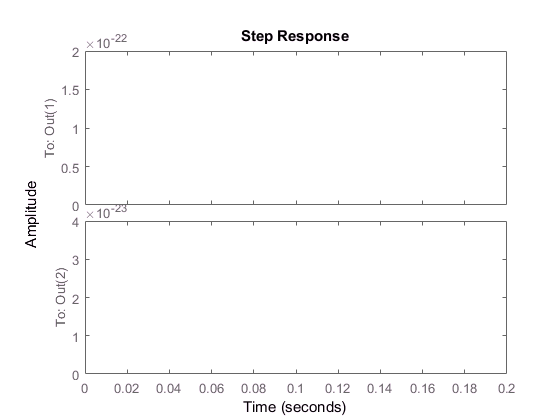

step(syscl)